# Image-Based Defect Detection for Manufacturing Inspection

By Diego Hidalgo, Diego Rosales and Enoch Ho.

## Introduction

This project builds a hybrid inspection system for the `metal_plate` category of the MPDD dataset (please check their GitHub). The system combines image processing evidence like rust color, scratch edges; with a transfer learned classification network based on ResNetwh-18. The image processing pipeline create a interpetable evidence overlay and tracks shapes and color evidence. Furthermore, the AI detects the four different categories: good, major_rust, total_rust, and scratches and provides the final PASS/FAIL decision. Sections below follow the project's five tasks in order.

## Task 1: Explore and Organize Image Dataset

The original MPDD dataset was designed for unsupervised learning (training using only good parts). Since this project is using a supervised learning classification to identify the four specific categories, we combined all images and created our own arrangement.

###  Define Dataset Directory

% You must change the 'root' directory path below to match the exact 
% location of the 'metal_plate' dataset on your local computer before running.


root = "C:\Users\egocr\Documents\GitHub\ImageDefectTeam9\metal_plate"; % Right now using my own image directory

### Generating the CSV (Commented out)

This section shows the original logic used to scan the folders, label the data as PASS/FAIL, and generate the 'labels.csv' file. You must uncomment and run this section at least once if you are running this project on a new computer.

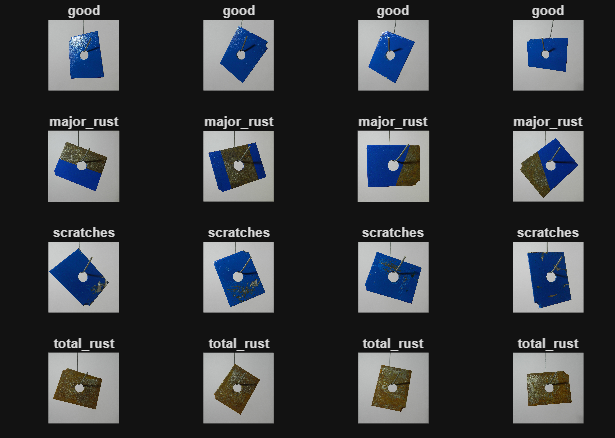

% IMPORTANT: If you downloaded this project to a new machine.
% Uncomment and run this block once with your updated 'root' directory. 
% This will regenerate the CSV so it matches your local file paths.

%{
metal_plate Folder Tree
metal_plate
├───ground_truth
│   ├───major_rust
│   ├───scratches
│   └───total_rust
├───test
│   ├───good
│   ├───major_rust
│   ├───scratches
│   └───total_rust
└───train
    └───good
%}
%{
% Define the specific folders and labels

folders = {
    fullfile(root,"train","good"),        "good"
    fullfile(root,"test","good"),         "good"
    fullfile(root,"test","major_rust"),   "major_rust"
    fullfile(root,"test","scratches"),    "scratches"
    fullfile(root,"test","total_rust"),   "total_rust"
    };

% Initialize empty string

filepath = strings(0,1);
defectType = strings(0,1);


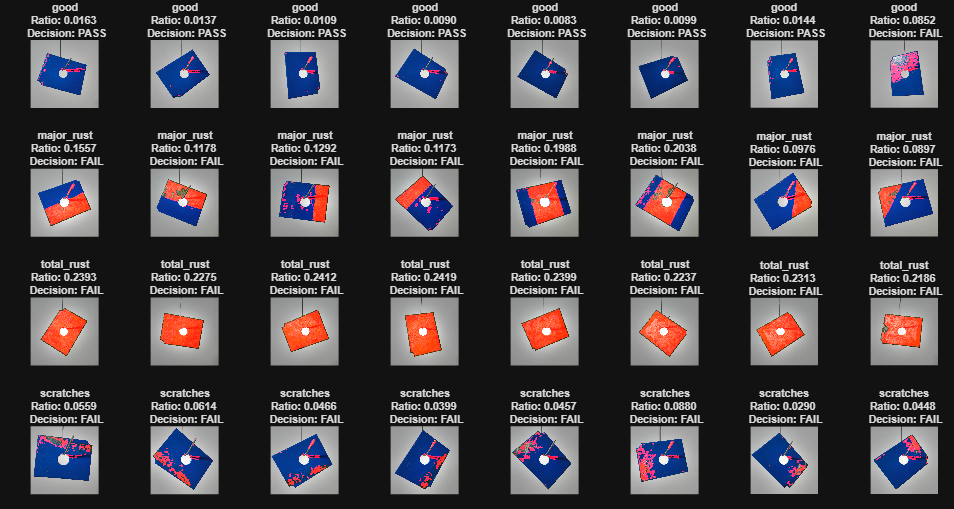

% Loop through each folder to find images and assign labels

for i = 1:size(folders,1)
    files = dir(fullfile(folders{i,1}, "*.png"));
    for j = 1:numel(files)
        filepath(end+1,1) = fullfile(files(j).folder, files(j).name);
        defectType(end+1,1) = folders{i,2};
    end
end

% Create pass and fail array

passOrFail = repmat("FAIL", size(defectType));
passOrFail(defectType == "good") = "PASS";

% Combine the three arrays into the labels.csv 

datatable = table(filepath, defectType, passOrFail);
writetable(datatable, fullfile(root, "labels.csv"));

%}

### Creating the Datastore 

This section reads the pre-generated CSV and builds the imageDatastore. The datastore includes the image file paths, folder locations, and their corresponding labels.

%Load the CSV into a table

datatable = readtable(fullfile(root,"labels.csv"), ...
    'Delimiter', ',', ...
    'TextType', 'string', ...
    'VariableNamingRule', 'preserve');

% Create the Datastore

datastore = imageDatastore(datatable.filepath);
datastore.Labels = categorical(datatable.defectType);

### Visualizing the Dataset 

To verify our data loaded correctly, the grid below displays four random images from each category.

% Randomly sample exactly 4 images from each category
sampleDS = splitEachLabel(datastore, 4, 'randomized');

% Create 4x4 grid
figure('Name', 'Dataset Preview', 'Position', [100, 100, 800, 800]);
tiledlayout(4, 4, 'TileSpacing', 'compact', 'Padding', 'none');

for i = 1:numel(sampleDS.Files)
    nexttile;

    % Read the image and display it
    img = readimage(sampleDS, i);
    imshow(img);

    % Set the label as the title
    categoryLabel = string(sampleDS.Labels(i));
    title(categoryLabel, 'Interpreter', 'none', 'FontSize', 10);
end

### Takeaways

We converted an unsupervised dataset into a supervised format, categorizing all images into PASS/FAIL labels and their specific defect types. By saving our table into a CSV we avoid reaping this conversion, allowing the program to be more efficient.

The grid serves as a sanity check showing that the datastore is correctly pulling the images and attaching the right labels before we begin training.

## Task 2: Build a Single-Image Inspection Function

Before training the AI, in this section we built a image processing pipeline to analyze specific evidence on the metal plates. This script takes an image, standardizes its size, corrects lighting, and looks for defects based on color and shape. The system gives a red overlay that highlights the defects showing why a part passed or failed. Also it provides a baseline decision: Pass or Fail. 

### Finding Defects

Rust and scratches are different, so we used two different strategies:

- **Rust (Color):** Rust is detectable by its color. We convert the image to HSV and looked for look for specific colors and saturations via trial and error. That lets us identify the rust.

- **Finding Scratches (Texture/Edges):** Scratches are detectable by their shape. We convert the image to black and white and use an edge detection algorithm to find scratches.

### Problem and Solution

Images often have shadows and uneven lighting. To fix this, we used a lighting correction function (`imflatfield` or in our code: `correctLighting.m`) to flatten the brightness across the image. However, the metal plate experienced a glowing halo around the edges of the plate.

**Our Solution:** We made the functions ignore the background and the outer edges, forcing it to find defects strictly inside the interior of the plate. This made the glowing halo irrelevant.

### Showcase of the Overlay Detection and Baseline Decision

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        6.25% |       13.04% |       2.0057 |       1.8819 |      1.0000e-04 |
|       1 |           5 |       00:00:08 |       37.50% |       47.83% |       1.5035 |       1.4703 |      1.0000e-04 |
|       2 |          10 |       00:00:13 |       56.25% |       60.87% |       1.2664 |       1.3016 |      1.0000e-04 |
|       3 |          15 |       00:00:18 |       62.50% |       56.52% |       0.9498 |   

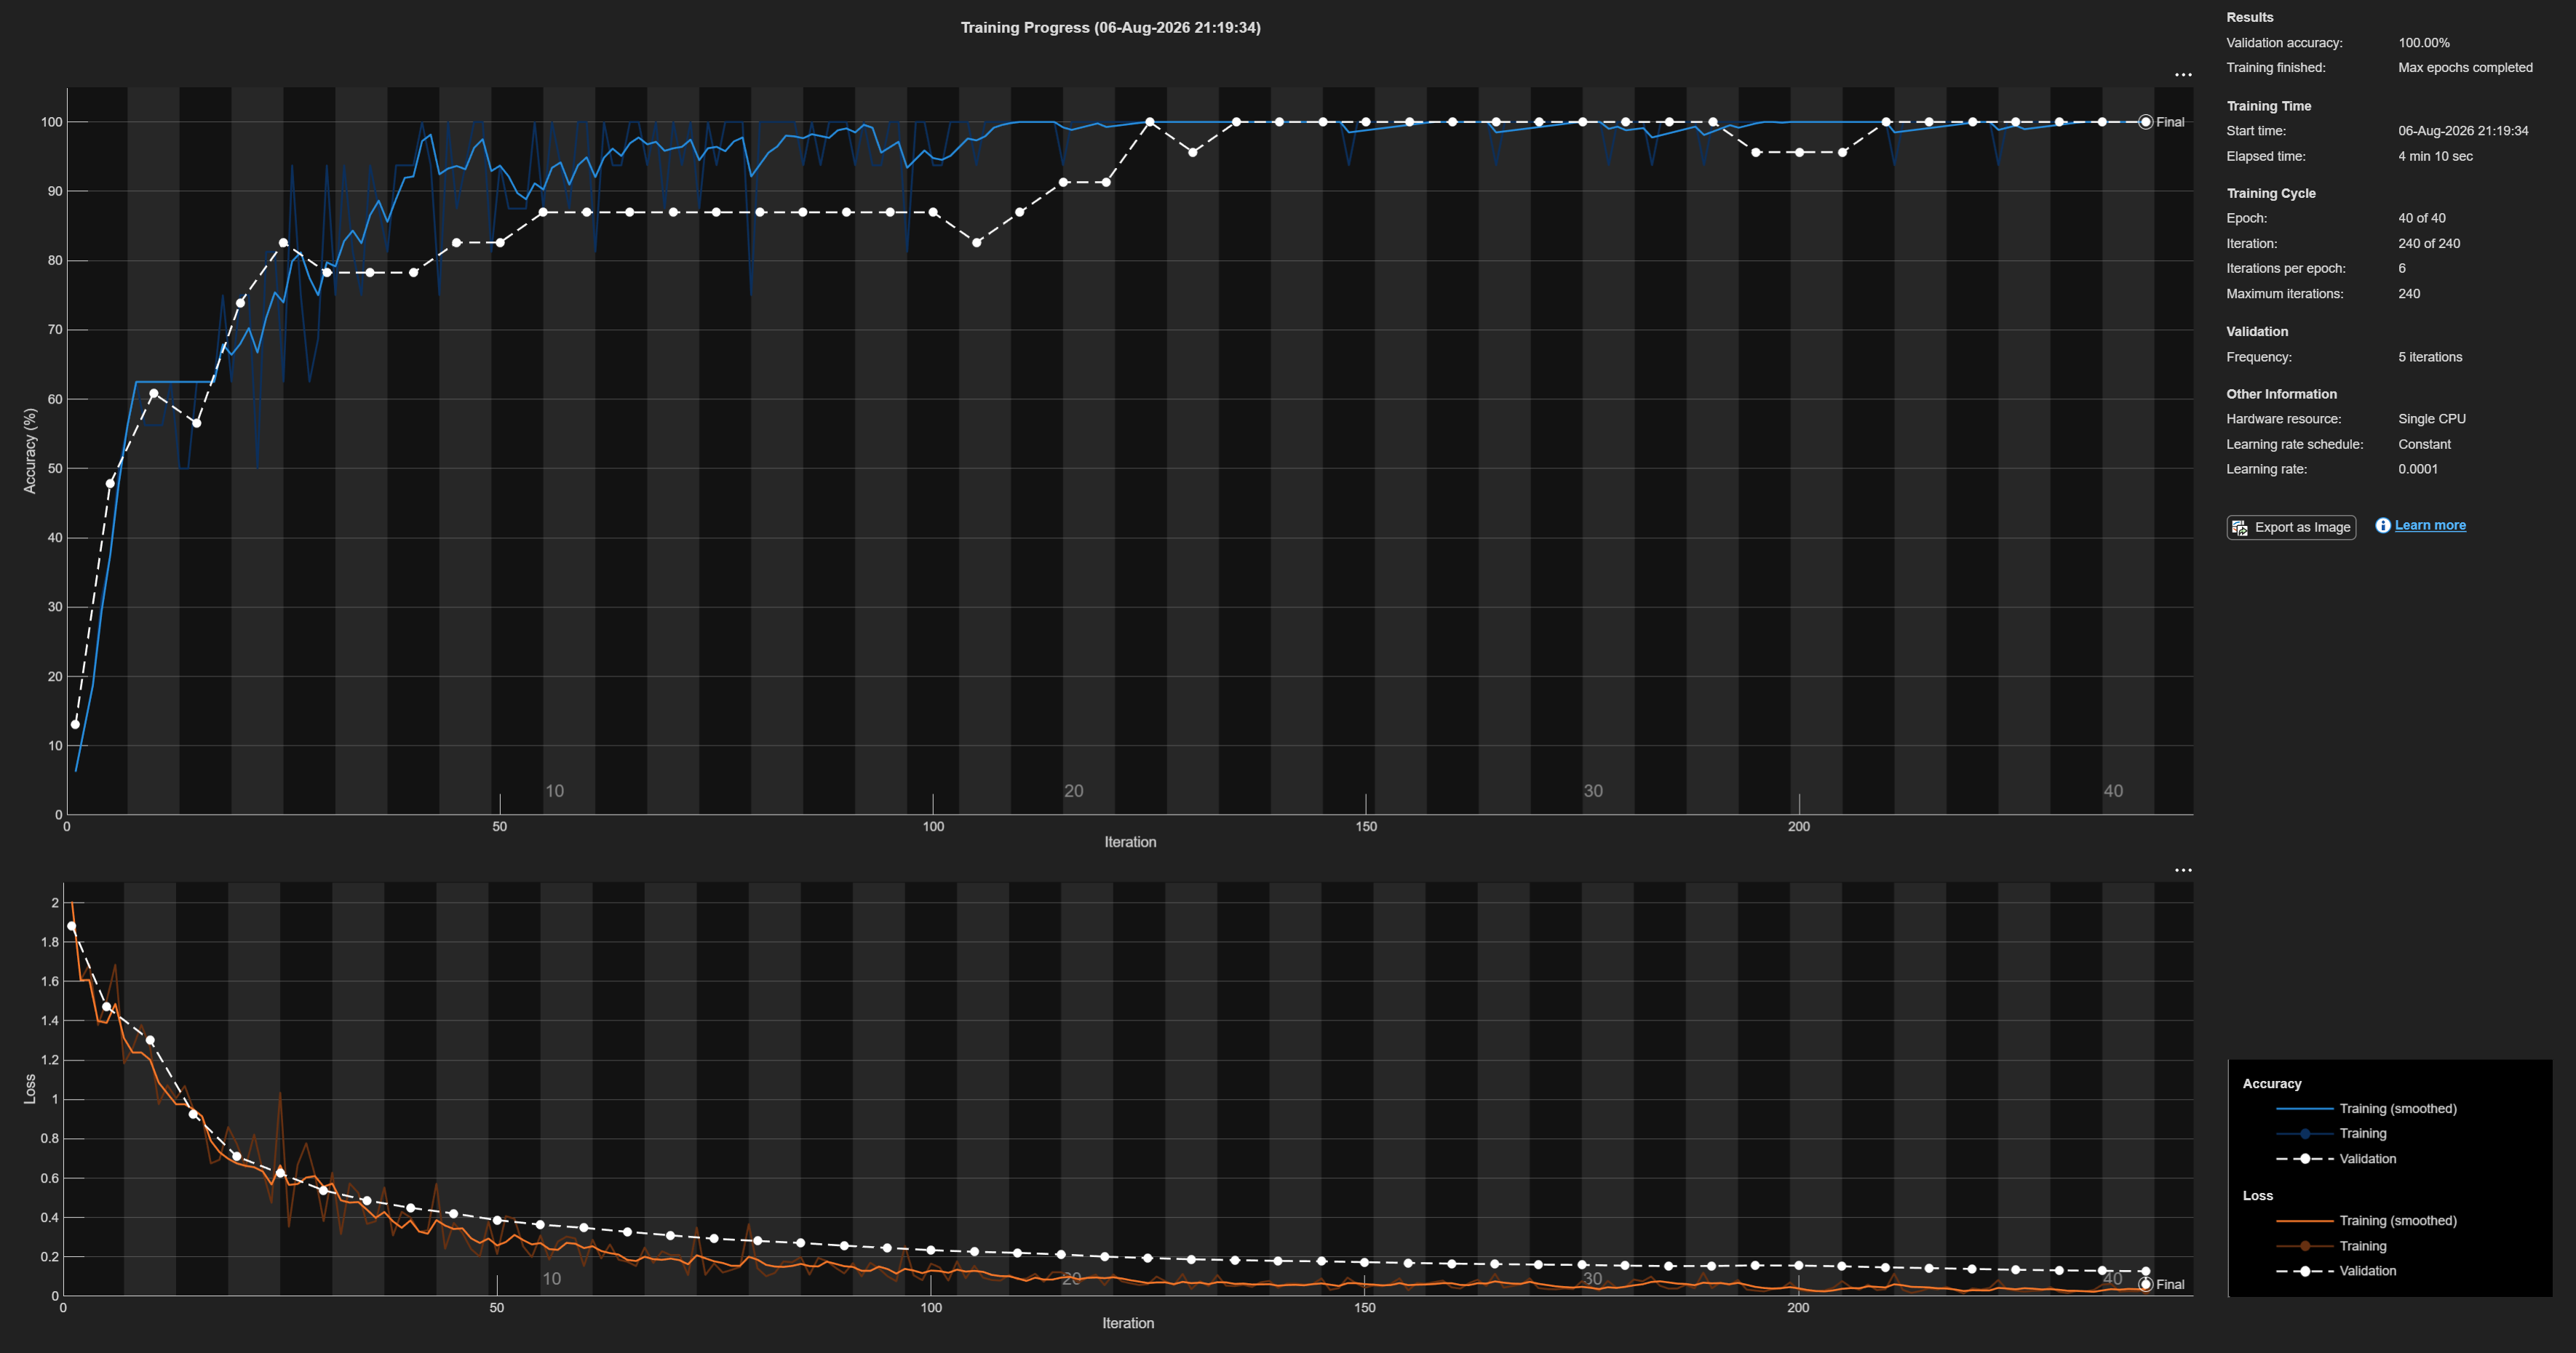

defectCategories  = ["good", "major_rust", "total_rust", "scratches"];

% Create a grid
figure('Name', 'Pipeline Overlay Results', 'Position', [100, 100, 1500, 800]);
tiledlayout(4, 8, 'TileSpacing', 'compact', 'Padding', 'none');

for c = 1:length(defectCategories)
    
    currentLabel = defectCategories(c);
    
    idx = find(datatable.defectType == currentLabel, 8);
    
    for i = 1:length(idx)
        
        nexttile; 
        
        I = imread(datatable.filepath(idx(i)));
        
        [rgb, gray] = standardizeImage(I, [512 512]);
        partMask = segmentPart(rgb);         
        [rgbCorrected, grayCorrected] = correctLighting(rgb, gray);

        [evidenceMask, rustMask, scratchMask] = defectEvidence(rgbCorrected, grayCorrected, partMask);
        
        metrics = extractMetrics(evidenceMask);
        baselineDecision = decideRules(metrics);

        overlay = rgbCorrected;
        redChannel = overlay(:,:,1);

        redChannel(evidenceMask) = 255; 
        overlay(:,:,1) = redChannel;
        
        imshow(overlay);
        
        titleString = sprintf('%s\nRatio: %.4f \n Decision: %s', ...
            currentLabel, metrics.areaRatio, baselineDecision); 

        title(titleString, 'Interpreter', 'none', 'FontSize', 8);

    end
end

### **Takeaways**

Across this 32-image sample, the image processing pipeline successfully highlights true defects (rust and scratches) with impressive accuracy (31/32 for this sample).

The pipeline occasionally fails a good metal plate (False Positives). We suspect this happens because the edge detection algorithm sometimes mistakes harsh lighting glares for scratches. We realize that our lighting correction cannot eliminate 100% of reflections.

The `areaRatio` metric is an incredibly strong and consistent factor of a metal plate condition. For detailed calculations and the exact logic behind our decision metrics, please look at the `defectEvidence.m` and `extractMetrics.m` functions

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

In this section we created a deep learning AI network to give the final decision. Because our factory dataset is extremely small (151 in total), training a neural network from scratch would lead to overfitting. To solve this, we use Transfer Learning. We are using a pre-trained ResNet-18 model and by replacing its final classification layers, we tuned the network to specifically recognize our four metal plate categories.

### Dataset Preparation

70% Training, 15% Validation, 15% Testing

[trainImds, remainderImds] = splitEachLabel(datastore, 0.7, 'randomized');
[valImds, testImds] = splitEachLabel(remainderImds, 0.5, 'randomized');

### Image Augmentation

Because our dataset is small, we used image augmentation to artificially generate more training data. By randomly flipping, shifting, and rotating the original images, we created new fake variations. This also simulates a factory line inspection and prevents the AI from just memorizing the original images, improving accuracy in test and validation data.

inputSize = [224 224 3];

summary = 4×4 table
    agreementTier    trueLabel    GroupCount    sum_AIDecisionIsCorrect
    _____________    _________    __________    _______________________

    "Agree-FAIL"      "FAIL"          9                    9           
    "Agree-PASS"      "PASS"          9                    9           
    "Unsure"          "FAIL"          1                    0           
    "Unsure"          "PASS"          3                    3           


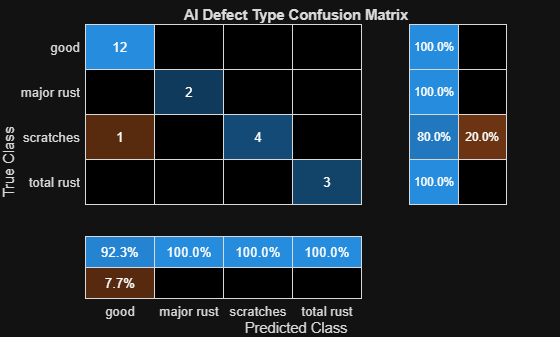


% Random changes to the images (e.g. rotations, reflections)

augmenter = imageDataAugmenter( ...
    'RandRotation', [-15 15], ...             % 15 degrees Rotation
    'RandXReflection', true, ...              % Flip left/right
    'RandYReflection', true, ...              % Flip up/down
    'RandXTranslation', [-10 10], ...         % Shift left/right up to 10 pixels
    'RandYTranslation', [-10 10]);            % Shift up/down up to 10 pixels

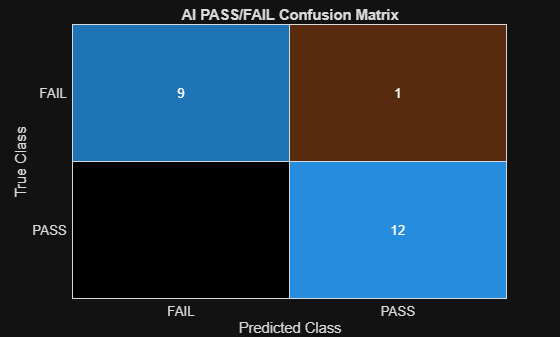


augTrain = augmentedImageDatastore(inputSize(1:2), trainImds, ...
    'ColorPreprocessing','gray2rgb', 'DataAugmentation', augmenter);

augVal   = augmentedImageDatastore(inputSize(1:2), valImds,   'ColorPreprocessing','gray2rgb');

### Transfer Learning Setup

We followed challenge recommendations to use the ResNet-18 model. However, the model was trained to recognize 1,000 different objects. So we replaced last two layers with custom layers restricted to our four categories (good, major_rust, total_rust, and scratches).

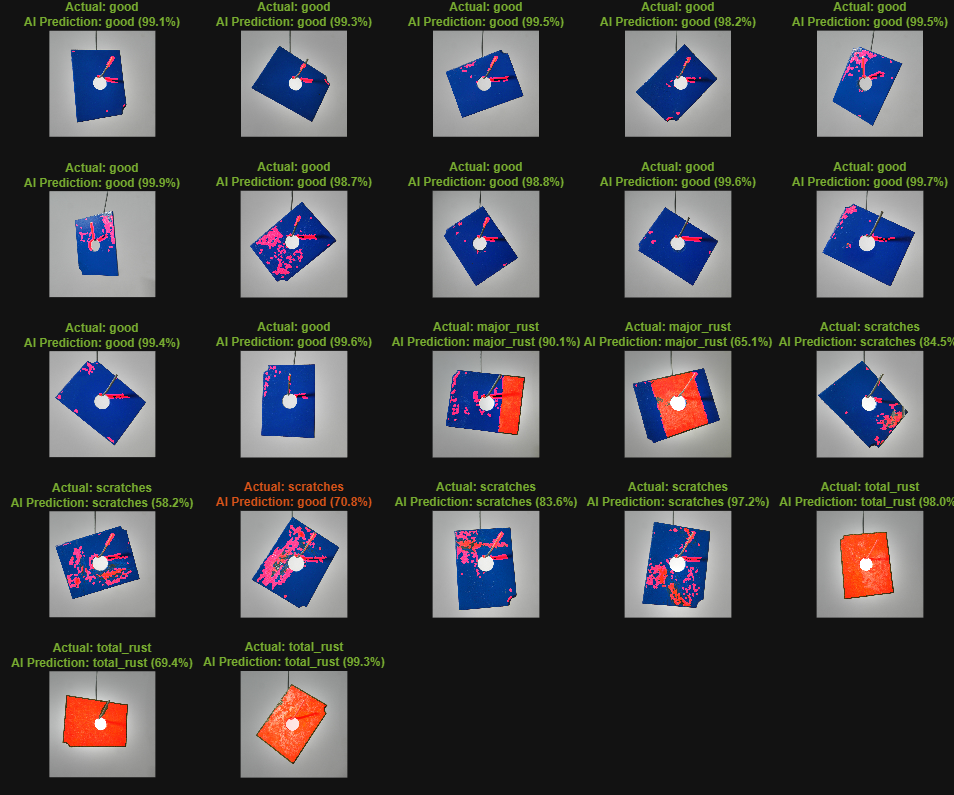

% Load the pre-trained model
net = resnet18;
lgraph = layerGraph(net);

numClasses = numel(defectCategories);  

% Create two new layers
newFC = fullyConnectedLayer(numClasses, 'Name','new_fc', ...
    'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
newClassLayer = classificationLayer('Name','new_classoutput');

% Replace old layers
lgraph = replaceLayer(lgraph, 'fc1000', newFC);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);

### Network Training

In this section, we trained our AI network with the options below. If you want to train it yourself, you can run the code. Our best network was trained using an Intel i7-265k processor with 32GB-5600 MT/s of RAM (stable configuration). We used validation data to check how the model was doing during training and to prevent overfitting. Overfitting is when the AI starts to memorize the training images instead of actually learning the features of the images.

To ensure the report remains consistent, we are using `MyBestNet.mat AI model`. Because training involves some randomness, we ran the exact same configuration 10 different times and saved the best one. For the report, we are showing how the training performed, but keep in mind the training graph shown is an example run using these options, not the exact live model we are evaluating.

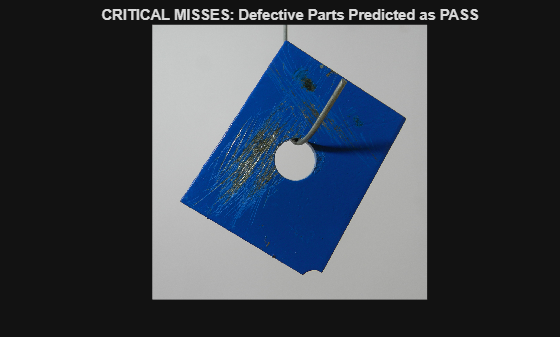

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 40, ...
    'MiniBatchSize', 16, ...
    'ValidationData', augVal, ...
    'ValidationFrequency', 5, ...
    'ValidationPatience', 5, ...
    'OutputNetwork','best-validation-loss', ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Uncomment if you want to train the network again
  


trainedNet = trainNetwork(augTrain, lgraph, options);
% save('trainedNet.mat', 'trainedNet');


% load('trainedNet.mat', 'trainedNet');

load('MyBestNet.mat', 'trainedNet');


### Combine outputs into a hybrid inspection result

To bring everything together, we created our final function: `inspectPart.m`. This function takes a single image of a metal plate and runs it through the image processing pipeline (Task 2) and the trained AI network (Task 3). For the complete code and logic, please look at the `inspectPart.m` function.

The outputs of the `inspectPart.m function are:`

- `finalLabel`**:** The specific defect category (e.g., "good", "major_rust") decided by the AI.

- `confidenceScore`**:** A percentage showing exactly how confident the AI is in its decision.

- `evidenceOverlay`**:** A red overlay that highlights the defects by the image processing pipeline.

- `evidenceMetrics`**:** The data calculated by the image processing pipeline.

- `baselineDecision`**:** The PASS/FAIL decision made by the image processing pipeline.

% function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision] = inspectPart(I, net);
% Function in inspectPart.m

### Problem and Solution Takeaways

At first, our model's performance was low about 80% accuracy. To fix this, we increased the number of our image augmentation and changed our training options from 40 epochs instead of just 5. Also we used validation data to automatically stop the training before it could overfit. This changed successfully boosted our final model to a 95-100% accuracy (depending on the random variance of the training run).

### Takeaways

Overall, the trained network achieved excellent accuracy on both the validation and test images. We will break down these exact results in the next section (Task 4).

We decided that instead of using a PASS or FAIL decision for the AI, we would train it to predict the 4 different categories. This made the decision much more complex because the AI now needed to classify specific defects, like scratches or the exact amount of rust. Actually, this decreased our accuracy at first. During our early training attempts, the model was really confused between 'scratches' and 'good,' or 'major rust' and 'total rust,' which made the training much harder. But in the end, we achieved a highly accurate model while keeping the 4 categories we wanted to use.

## Task 4: Evaluate Inspection System Performance

In this section, we test our inspection function. We ran 22 test images through our `runInspectioSuit.m` function that gets our AI model and datastore. This functions uses `inspectPart.m` function to see how the AI and the image processing pipeline performs. Overall, the system successfully evaluated the metal plates and achieved a 95-100% accuracy.

**Evaluation Disclaimer:** Due to the randomized nature of the `splitEachLabel` function and the fact that we are loading a previously saved model (`MyBestNet.mat`), there is likely some overlap between these test images and the original training data. While this means the accuracy shown in the matrices below is slightly optimistic, we estimate a similar performance if you were to train the network again and follow the correct procedure.

### Run AI Evaluation

results = runInspectionSuite(testImds, trainedNet);

### Print  Agreement Summary Table

The table bellow shows if task 2 image processing pipeline and task 3 AI prediction agreed, and shows if AI decision was correct. 'Unsure' means the two systems disagreed. The final column (`sum_AIDecisionIsCorrect`) represents how many times the AI's decision was actually correct within each group.

summary = groupsummary(results, {'agreementTier','trueLabel'}, 'sum', 'AIDecisionIsCorrect')

### Defect Type Confusion Matrix

Confusion matrix of the 4 defect types.

cleanTrueDefect = strrep(results.trueDefectType, '_', ' ');

Total parts inspected: 22


cleanAIPred = strrep(results.aiLabel, '_', ' ');

Yield (PASS rate): 59.1%


figure

Defect rate: 40.9%


confusionchart(categorical(cleanTrueDefect), categorical(cleanAIPred), ...
    'Title', 'AI Defect Type Confusion Matrix', ...
    'RowSummary','row-normalized', 'ColumnSummary','column-normalized')

### Pass/Fail Confusion Matrix

Confusion matrix of the pass or fail.

figure

    trueDefectType    GroupCount
    ______________    __________

     "major_rust"         2     
     "scratches"          4     
     "total_rust"         3     



confusionchart(categorical(results.trueLabel), categorical(results.aiPred), ...
    'Title', 'AI PASS/FAIL Confusion Matrix')

### AI test images all cases

This grid displays all the test images with the defect overlay applied. The text shows the actual label, the AI's prediction, and the AI's confidence level. If the text is green, it means the AI's decision was correct.

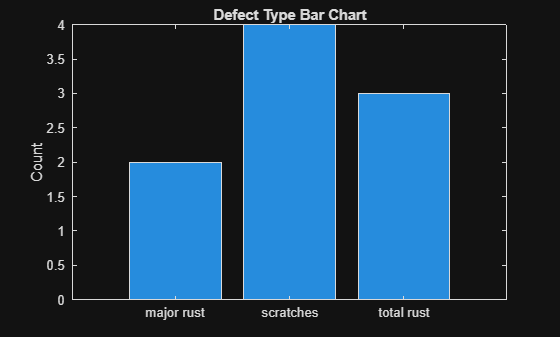

numTotalImages = numel(testImds.Files);

figure('Name', 'Full AI Batch Testing', 'Position', [100, 100, 1200, 1000]);


tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'none');

for i = 1:numTotalImages
    nexttile;
    
    I = readimage(testImds, i);

    actualRealLabel = string(testImds.Labels(i)); 
    
    [finalLabel, confidenceScore, evidenceOverlay, ~, ~] = inspectPart(I, trainedNet);
    finalLabel = string(finalLabel); 
    
    maxConf = max(confidenceScore); 
    
    imshow(evidenceOverlay);
    
    titleStr = sprintf('Actual: %s\nAI Prediction: %s (%.1f%%)', ...
        actualRealLabel, finalLabel, maxConf * 100);
    
    % Color the text
    if actualRealLabel == finalLabel
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#77AC30'); % Green
    else
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#D95319'); % Red
    end
end

### AI failure cases

This section checks for Critical Misses. A critical miss happens if the AI passes a defective metal plate as good when it is actually broken.

missedIdx = find(results.trueLabel == "FAIL" & results.aiPred == "PASS");

          Condition          Accuracy    False Alarms    Critical Misses
    _____________________    ________    ____________    _______________

    "Clean (baseline)"       0.95455          0                0.1      
    "Blur (sigma=2)"         0.95455          0                0.1      
    "Blur (sigma=4)"         0.86364          0                0.3      
    "Noise (gaussian)"             1          0                  0      
    "Noise (salt&pepper)"          1          0                  0      
    "Low contrast"           0.95455          0                0.1      
    "High contrast"          0.86364          0                0.3      



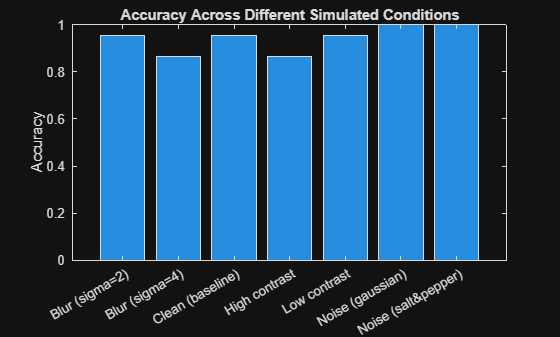


if isempty(missedIdx)
    disp('No defective parts were accidentally passed!')
else
    missedImages = cell(1, numel(missedIdx));
    for k = 1:numel(missedIdx)
        missedImages{k} = imread(results.filepath(missedIdx(k)));

    end

    figure
    montage(missedImages)
    title('CRITICAL MISSES: Defective Parts Predicted as PASS')
end

### **Takeaways**

The system successfully caught every single defective part (depending on the run is usually between 1 or 0), meaning zero broken plates would have accidentally passed the inspection.

The Agreement Summary Table proves the value of adding Deep Learning. In all cases (depending on the run is usually all or most of them) where the image processing pipeline and the AI disagreed, the AI made the correct decision.

The system is highly accurate. The only limitation of these results is the slight inaccuracy caused by the random data splitting explained earlier on the section. 

## **Factory Production Analytics**

This sections shifts our focus from evaluating the software's accuracy (how well the AI makes decisions) to evaluating the metal plates themselves (the actual production data a business would use). Using the model's predictions, we generated a manufacturing yield report.

### Yield & Defect Rates

How many of the metal plates actually passed. (This is AI decision)

totalParts = height(results);
passCount = sum(results.aiPred == "PASS");
yieldRate = passCount / totalParts * 100;

fprintf('Total parts inspected: %d\n', totalParts);
fprintf('Yield (PASS rate): %.1f%%\n', yieldRate);
fprintf('Defect rate: %.1f%%\n', 100 - yieldRate);

### Defect Type Table and Bar Chart

Specific type of the defect metal plates. (This is AI decision)

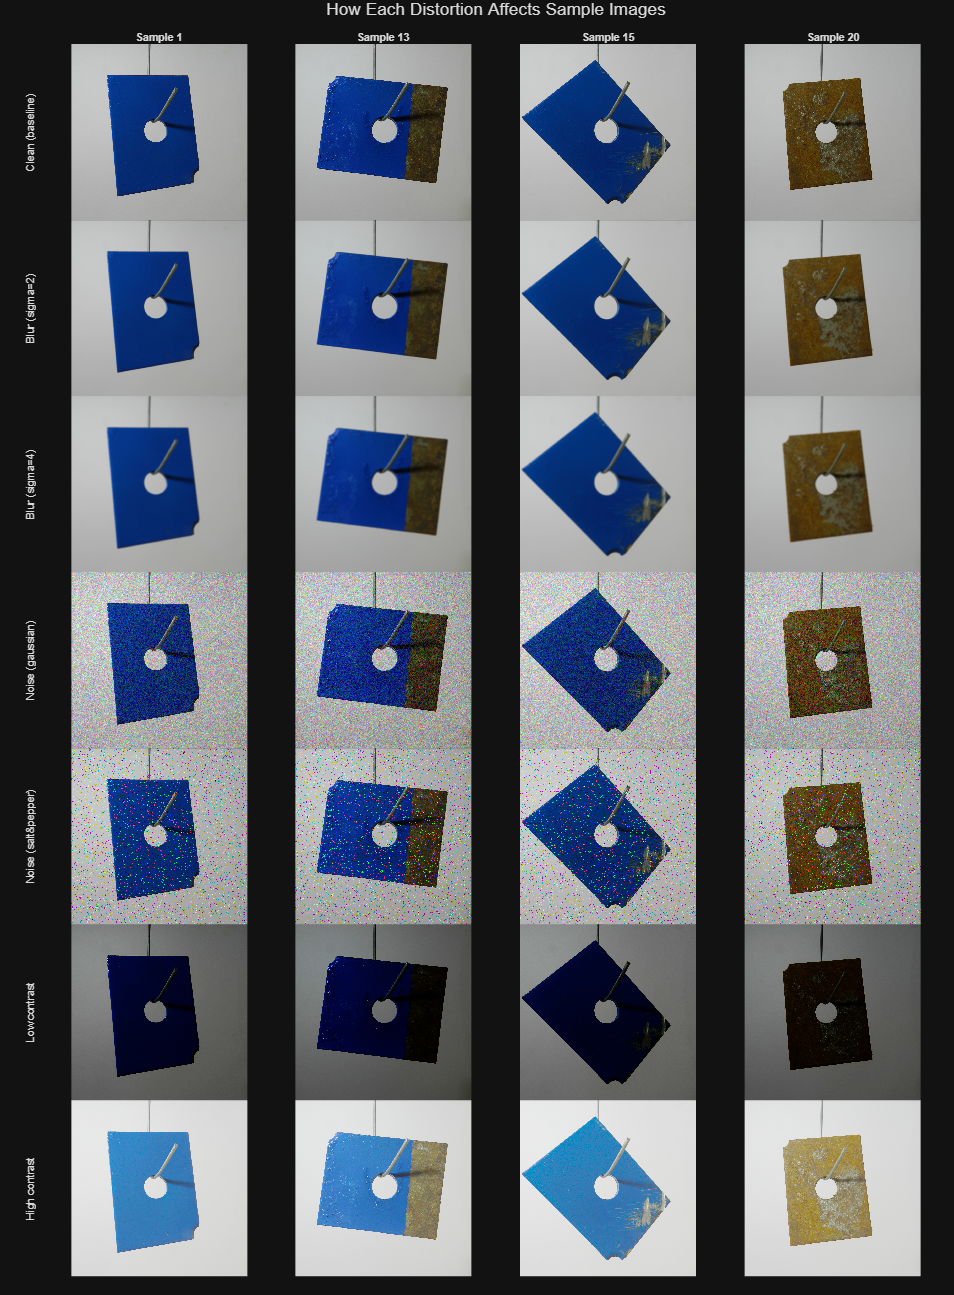

defectBreakdown = groupsummary(results(results.aiPred=="FAIL",:), 'trueDefectType');

disp(defectBreakdown)
cleanDefectTypes = strrep(defectBreakdown.trueDefectType, '_', ' ');

figure
bar(categorical(cleanDefectTypes), defectBreakdown.GroupCount)
title('Defect Type Bar Chart')
ylabel('Count')

### Takeaways

The system tracks the overall pass/fail rate, meaning a manager can quickly identify if something is wrong on the assembly line. 

The system breaks down the exact type of defect, making troubleshooting much easier.

## Task 5: Test and Evaluate System Robustness

In this section, we simulate real world visual distortions since we know that factory conditions are rarely perfect. By applying different levels of blur, noise, and contrast to our test images, we can measure the AI's robustness. 

### Setting Conditions to Test

These are the specific conditions we chose to test. We included two different levels for each category: blur, noise, and contrast.

conditions = {
    "Clean (baseline)",     []
    "Blur (sigma=2)",       @(I) applyBlur(I, 2)
    "Blur (sigma=4)",       @(I) applyBlur(I, 4)
    "Noise (gaussian)",     @(I) applyNoise(I, 'gaussian', 0.01)
    "Noise (salt&pepper)",  @(I) applyNoise(I, 'salt & pepper', 0.05)
    "Low contrast",         @(I) applyContrast(I, 2.5)
    "High contrast",        @(I) applyContrast(I, 0.4)
    };

### Test Accuracy, False Alarms and Critical Misses for Each Condition

To evaluate performance, we tracked Overall Accuracy, False Alarms (accidentally failing a good part) and Critical Misses (accidentally passing a broken part).

The results can show that digital noise does not negatively affect our AI. However, Low contrast lighting is a major vulnerability, causing the system's accuracy to drop. The other distortions, like blur and high contrast, only had a minor impact on overall performance.

robustnessResults = table();
for c = 1:size(conditions,1)
    label = conditions{c,1};
    fcn = conditions{c,2};
    r = runInspectionSuite(testImds, trainedNet, fcn);

    acc = mean(r.AIDecisionIsCorrect);
    falseAlarms  = sum(r.trueLabel=="PASS" & r.aiPred=="FAIL") / sum(r.trueLabel=="PASS");
    criticalMisses = sum(r.trueLabel=="FAIL" & r.aiPred=="PASS") / sum(r.trueLabel=="FAIL");

    robustnessResults = [robustnessResults; ...
        table(string(label), acc, falseAlarms, criticalMisses, ...
        'VariableNames', {'Condition','Accuracy','False Alarms','Critical Misses'})];
end

disp(robustnessResults)

### Bar Graph of Accuracy

The following bar chart shows the model's accuracy showed in the table above.

figure
bar(categorical(robustnessResults.Condition), robustnessResults.Accuracy)
title('Accuracy Across Different Simulated Conditions')
ylabel('Accuracy')
xtickangle(30)

### Example of Each Distortion

The grid below shows how these simulated conditions alter the appearance of the images before they are evaluated by the AI.

index = [1, 13, 15, 20];

figure('Name', 'Distortion Preview Grid', 'Position', [100, 100, 1400, 1900]);
tiledlayout(size(conditions,1), numel(index), 'TileSpacing', 'none', 'Padding', 'none');

for c = 1:size(conditions,1)
    fcn = conditions{c,2};
    for k = 1:numel(index)
        nexttile;
        I = readimage(testImds, index(k));
        if ~isempty(fcn)
            I = fcn(I);
        end
        imshow(I);
        if k == 1
            ylabel(conditions{c,1}, 'FontSize', 8, 'Interpreter', 'none');
        end
        if c == 1
            title(sprintf('Sample %d', index(k)), 'FontSize', 8);
        end
    end
end
sgtitle('How Each Distortion Affects Sample Images')

### Takeaways

The AI maintains a high accuracy across all tested conditions. 

## Interpretation of Results

### **Summary of Findings**

This project successfully built a hybrid inspection system. By combining an image processing pipeline with a Deep Learning AI, we created a system that is highly accurate. The image processing pipeline shows exactly where the defect is on the metal plate using the red overlay and the AI correctly classifies what the defect is. Furthermore, our robustness testing proved that the model is robust enough to handle real world issues and still maintain high accuracy rates.

### **Limitations of the Work**

The MPDD dataset only contains 151 images. While image augmentation helped, training an AI on such a small dataset always carries a risk of overfitting.

The images in this dataset have perfectly clean and uniform backgrounds. In the real world, this is not true. Because of this the AI had a much easier time classifying the parts than it would in a real industrial environment.

### **Practical Next Steps**

The immediate next step is to capture more images of metal plates in actual factory environments to train the AI on realistic backgrounds and increase the dataset.

We could expand the model's capabilities by training it to recognize different colored metal plates, or by adding entirely new defect categories like dents or cracks.

The final step would be deploying this MATLAB script onto an industrial camera to test its real time processing speed on an assembly line.

## References

**[1]** S. Jezek, M. Jonak, R. Burget, P. Dvorak, and M. Skotak, "Deep learning-based defect detection of metal parts: evaluating current methods in complex conditions," *2021 13th International Congress on Ultra Modern Telecommunications and Control Systems and Workshops (ICUMT)*, 2021, pp. 66-71. Dataset available at: [https://github.com/stepanje/MPDD](https://github.com/stepanje/MPDD)

This project was built using skills and information provided from the following MathWorks courses:

- MATLAB Onramp

- Image Processing Onramp

- Deep Learning Onramp

- Deep Learning Techniques in MATLAB for Image Application